# Data Prediction

load fisheriris.mat
[~, ~, s] = unique(species);
y = meas(:,4); % Response variable
rng(0);%seed
features = [meas(:,1:3),s,meas(:,1)+0.2*randn(150,1), randn(150,1)];%With redundant feature + noise

### Split Dataset(Training)

train_x = features(1:2:end,:);
train_y = y(1:2:end,:);

### Validation set

To be used for tuning hyper parameters

validate_x = features(2:4:end,:);
validate_y = y(2:4:end,:);

### Testing set

test_x = features(4:4:end,:);
test_y = y(4:4:end,:);

## Create Linear Model

%4th parameter is 4 since it contains the categories in the feature set
mdl = fitlm(train_x, train_y, "CategoricalVars",[4]);
mdl

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)     -0.64735     0.24019     -2.6952      0.008886
    x1              -0.09134    0.099204    -0.92073        0.3605
    x2               0.29863    0.062961       4.743    1.1431e-05
    x3               0.27685    0.059804      4.6293    1.7361e-05
    x4_2             0.65501     0.15499      4.2261    7.3544e-05
    x4_3              1.0534     0.20785      5.0682    3.3829e-06
    x5             -0.022648    0.079215    -0.28591       0.77583
    x6             -0.033905

pdct_lm = predict(mdl, test_x);

### Measure Error

%Mean square error
MSE = mean((test_y - pdct_lm).^2);
MSE

MSE = 0.0306

### Plot

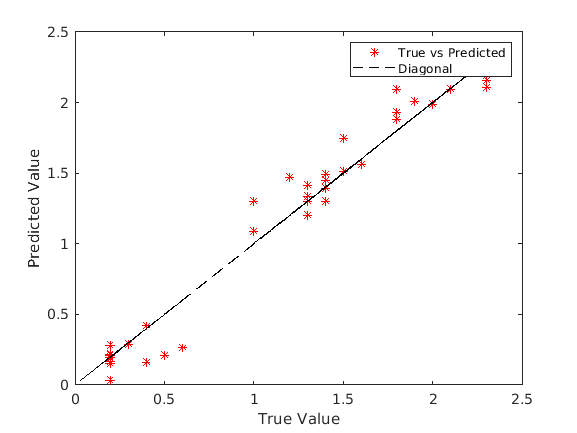

figure(1);
plot(test_y, pdct_lm, 'r*');
xlabel('True Value');
ylabel('Predicted Value');
rg = [min(test_y, pdct_lm), max(test_y, pdct_lm)];%Regression line
hold on
plot(rg,rg,'k--');
legend('True vs Predicted', 'Diagonal');
hold off

## Pearson Correlation test

[r, p] = corr(test_y, pdct_lm)

r = 0.9761

p = 8.7520e-25

### Remove features with High P-value(>0.05) using Stepwise Regression

mdl = stepwiselm(train_x, train_y,"constant","Upper","linear","CategoricalVars",[4]);

1. Adding x4, FStat = 534.8125, pValue = 6.210477e-44
2. Adding x2, FStat = 27.213, pValue = 1.72503e-06
3. Adding x3, FStat = 15.8445, pValue = 0.00016586
4. Adding x1, FStat = 5.2375, pValue = 0.025172


mdl

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -0.67337     0.24067    -2.7979     0.0066615
    x1             -0.11989    0.052386    -2.2886      0.025172
    x2              0.31872     0.06164     5.1706    2.1708e-06
    x3              0.27098    0.059938     4.5211    2.4843e-05
    x4_2            0.69158     0.15465     4.4719    2.9699e-05
    x4_3             1.0856     0.20851     5.2066    1.8899e-06


Number of observations: 75, Error degrees of freedom: 69
Root Mean Squared Error: 0.152
R-squared: 0.965,  Adjusted R-Squared: 0.963
F-statistic vs. cons

pdct_slm = predict(mdl, test_x);
figure(2);
EstimationErrorPlot(pdct_slm, test_y);

'EstimationErrorPlot' is not found in the current folder or on the MATLAB path, but exists in:
    /MATLAB Drive/DataPrediction

Change the MATLAB current folder or add its folder to the MATLAB path.

## For the case of non-linear Highly Discontinued data

% Problem case
mns = mean(features(1:2:end,:));
partitioned_y = features(:,1)+2*(features(:,1)>mns(1))+features(:,2)+10*(features(:,2)>mns(2))+ ...
    features(:,3)+50*(features(:,3)>mns(3))+features(:,4)+100*(features(:,4)>mns(4));
subset = features(:,1:4);
train_x = subset(1:2:end,:);
validate_x = subset(2:4:end,:);
test_x = subset(4:4:end,:);
train_y = partitioned_y(1:2:end);
validate_y = partitioned_y(2:4:end);
test_y = partitioned_y(4:4:end);
mdl = stepwiselm(train_x, train_y,"constant","Upper","linear","CategoricalVars",[4]);
mdl

pdct_partslm = predict(mdl, test_x);
EstimationErrorPlot(pdct_partslm, test_y);

## Using Regression Tree

mdl = fitrtree(train_x, train_y, "CategoricalPredictors", [4]);
view(mdl, 'Mode', 'graph');

### Hyper parameter Tuning

%mdl = fitrtree(train_x, train_y, "CategoricalPredictors", [4], "MaxNumSplits",3,"MinParentSize",2);
%MinParentSize how many training observations must contribute to the learning process for each decision node
err = zeros(20,20);
for i=1:20
    for j=1:20
        mdl = fitrtree(train_x, train_y, "CategoricalPredictors", [4], "MaxNumSplits",3*i,"MinParentSize",j+1);
        pdct_tree = predict(mdl, validate_x);
        err(i,j) = mean((pdct_tree - validate_y).^2);
    end
end
figure(3);
surf(2:21,3*[1:20],log(err));
xlabel("MinParentSize");
ylabel("MaximumSplits");
zlabel("MSE");
%We can use the log function, which can compress larger heights of the surface and make a lower minima easier to visualize.

### Find the minimum error

[i, j] = find(err==min(err(:)));
mdl = fitrtree(train_x, train_y, "CategoricalPredictors", [4], "MaxNumSplits",3*i(1),"MinParentSize",j(1)+1);

### Use Tuned Model

pdct_tree = predict(mdl, test_x);
figure(4);
EstimationErrorPlot(pdct_tree, test_y);
view(mdl, 'Mode', 'graph');

## Cross-Validation loss

The term loss often refers to the error function for machine learning classification and regression methods. Cross-validation is a process by which different splits of the dataset are created to iteratively choose training and testing sets for error analysis. Often, this process leads to an estimation of the error, that is more robust than simply choosing a single training testing set split, as we did in our example above

cvmdl = fitrtree([train_x; test_x], [train_y; test_y], "CategoricalPredictors", [4], "MaxNumSplits",3*i(1),"MinParentSize",j(1)+1);
rng(0);
cvloss(cvmdl);% Because this is a stochastic operation, initailize the random generator to get repeatable result
%returns an MSE equal to 0.38

## Polynomial Relation Sample

nonlinear_y = features(:,1).^1.5 + features(:,2).^2 + exp(features(:,3)) + s.^0.5 + randn(150,1);
train_y = nonlinear_y(1:2:end);
validate_y = nonlinear_y(2:4:end);
test_y = nonlinear_y(4:4:end);

### Try Stepwise regression

mdl = stepwiselm(train_x, train_y,"constant","Upper","linear","CategoricalVars",[4]);
pdct = predict(mdl, test_x);
figure(5);
subplot(2,2,1);
EstimationErrorPlot(pdct, test_y);
ylabel("Stepwise with linear terms");
%Stepwise with non-linear terms
mdl = stepwiselm(train_x, train_y,"CategoricalVars",[4]);
pdct = predict(mdl, test_x);
subplot(2,2,2);
EstimationErrorPlot(pdct, test_y);
ylabel("Stepwise with non-linear terms");

### Using MATLAB's built in Hyperparameter training process

mdl = fitrtree([train_x; validate_x], [train_y; validate_y], "CategoricalPredictors", [4], "OptimizeHyperparameters","auto");
%Automatically selects the best hyperparameters using cross-validation
%approach
pdct = predict(mdl,test_x);
subplot(2,2,3);
EstimationErrorPlot(pdct,test_y);
ylabel("Regression tree");

## Gaussian Process Regression(Good for non-linear)

This approach aims to fit a network of multidimensional Gaussian radial basis functions, to the input dataset

mdl = fitrgp([train_x; validate_x], [train_y; validate_y], "FitMethod", "sr", "OptimizeHyperparameters","auto");
pdct = predict(mdl, test_x);
subplot(2,2,4);
EstimationErrorPlot(pdct,test_y);
ylabel("Gaussian Process");